**Grant Roberts**

**MP710: Advanced MRI**

**11/20/2018**

# **Homework 6: Compressed Sensing**

## **1) Sparse Signals and Denoising**

**a) Sparse Signals **

x = [(1:5)/5 zeros(1,128-5)];
x = x(randperm(128));
y = x + 0.05*randn(1,128);

Show that $\min \left(\frac{1}{2}||\hat{x} -y||_2^2 +\lambda \frac{1}{2}||\hat{x} |{\left|\right.}_2^2 \right)$ has a close form solution: $\hat{x} =\frac{1}{1+\lambda \;}y$

By taking the first order derivative of the function above and setting the result to 0, we can find the minimum.

Firstly, if we fully express the L2 norm terms:


$$\frac{1}{2}\sum_{i=1}^n {\left(\hat{x_i } -y_i \right)}^2 +\frac{\lambda \;}{2\;}\sum_{i=1}^n {\hat{x} }^2 =\left\lbrack \frac{1}{2}{\left(\hat{x_1 } -y_1 \right)}^2 +\frac{\lambda }{2}{\hat{\left(x_1 \right)} }^2 \right\rbrack +\left\lbrack \frac{1}{2}{\left({\hat{x} }_2 -y_2 \right)}^2 +\frac{\lambda }{2}\;{\left(\hat{x_2 } \right)}^2 \right\rbrack +\;\ldotp \ldotp \ldotp$$


and taking the derivative:


$$\frac{\partial }{\partial \hat{x} }\left(\frac{1}{2}\sum_{i=1}^n {\left(\hat{{\;x}_i } -y_i \right)}^2 +\frac{\lambda \;}{2\;}\sum_{i=1}^n {\left(\hat{x_i } \right)}^2 \right)=\;\frac{1}{2}\left(\frac{\partial }{\partial \hat{x} }{\left({\hat{x} }_1 -y_1 \right)}^2 \right)+\frac{\lambda \;}{2}\left(\frac{\partial }{\partial \hat{x} }\left({x_1 }^2 \right)\right)+\;\ldotp \ldotp \ldotp \;\;$$

$$=\left(\hat{x_1 } -y_1 \right)\frac{\partial \left(\hat{x_1 } -y_1 \right)}{\partial \hat{x} }+\lambda \left({\hat{x} }_1 \right)\frac{\partial \left({\hat{x} }_1 \right)}{\partial \hat{x} }+\;\ldotp \ldotp \ldotp \;=\left(\hat{x_1 } -y_1 +\hat{{\;x}_2 } -y_2 +\;\ldotp \ldotp \ldotp \right)+\lambda \left({\hat{x} }_1 +{\;\hat{x} }_2 +\;\ldotp \ldotp \ldotp \right)$$
  

Thus:


$$\frac{\partial }{\partial \hat{x} }\left(\frac{1}{2}\sum_{i=1}^n |x_i -y_i {\left|\right.}^2 +\frac{\lambda \;}{2\;}\sum_{i=1}^n \left|\hat{x_i } {\left|\right.}^{2\;} \right.\right)=\hat{x} -y+\lambda \hat{x} =0\;$$



$$\hat{x} +\lambda \hat{x} =y$$


        
$$\to \left\lbrack \hat{x} =\frac{y}{\left(1+\lambda \;\right)}\right\rbrack$$


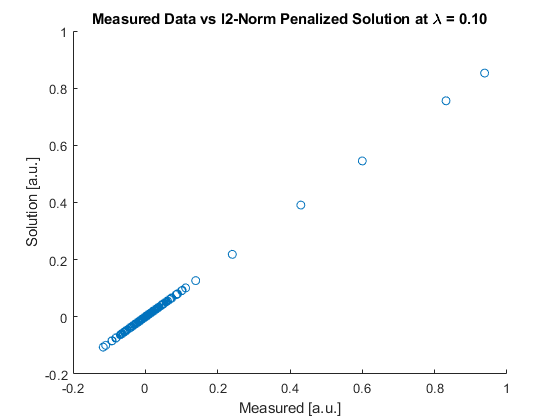

lambda = [0.01, 0.05, 0.1, 0.2];
xhat2 = y/(1+lambda(3));
figure; scatter(y,xhat2); title('Measured Data vs l2-Norm Penalized Solution at \lambda = 0.10'); xlabel 'Measured [a.u.]'; ylabel 'Solution [a.u.]';

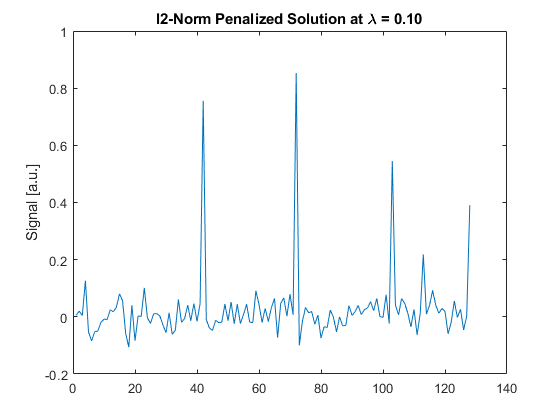

figure; plot(xhat2); title('l2-Norm Penalized Solution at \lambda = 0.10'); ylabel 'Signal [a.u.]';

The solution is still sparse, since it is simply a constant times the original signal. However, the noise is still apparent in the solution.

**b) Sparse Signals and the **$l^1$** Norm**

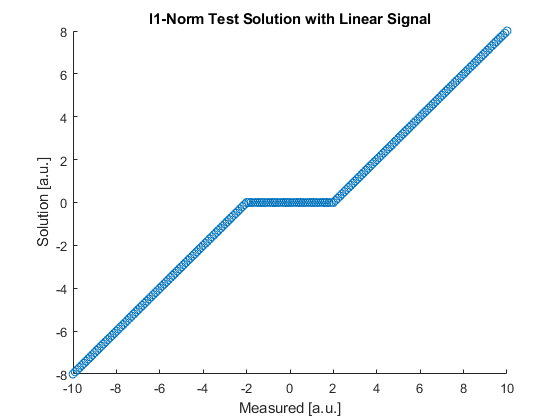

lambda_test = 2;
y_test = -10:0.1:10;
xhat_test = SoftThresh(y_test,lambda_test); 
figure; scatter(y_test, xhat_test);  title('l1-Norm Test Solution with Linear Signal'); xlabel 'Measured [a.u.]'; ylabel 'Solution [a.u.]';

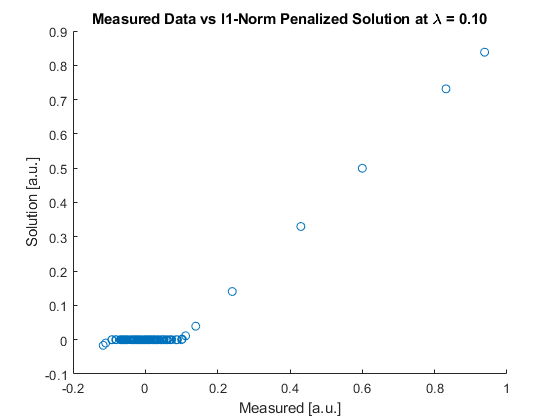

xhat = SoftThresh(y,lambda(3));
figure; scatter(y,xhat); title('Measured Data vs l1-Norm Penalized Solution at \lambda = 0.10'); xlabel 'Measured [a.u.]'; ylabel 'Solution [a.u.]';

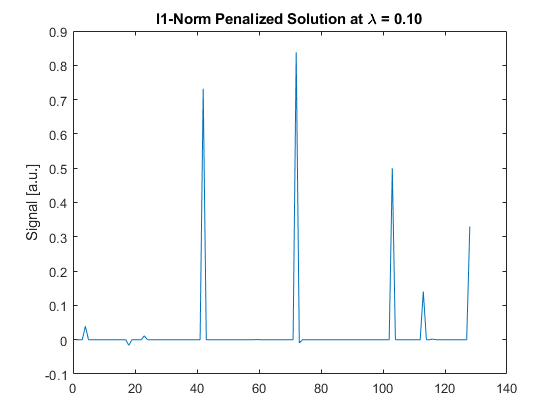

figure; plot(xhat); title('l1-Norm Penalized Solution at \lambda = 0.10'); ylabel 'Signal [a.u.]';

**c) Random Frequency Domain Sampling and Aliasing**

X = fftc(x,2);
Xu = zeros(1,128);
Xu(1:4:128) = X(1:4:128);
xu = ifftc(Xu,2)*4;

To explain why the undersampled image is equivalent to the solution, we need to look at the closed form solution calculated previously.


$$\hat{x} =\frac{y}{\left(1+\lambda \;\right)}$$


Equivalently, we can look at this in the Fourier domain:


$$\begin{array}{l}
F\hat{x} =F\frac{y}{\left(1+\lambda \;\right)}\\
\hat{X} =\frac{Y}{1+\lambda \;}
\end{array}$$


In this case, our Y is the undersample (measured) data.


$$\hat{X} =\frac{X_u }{1+\lambda \;}$$


Bringing this back into the image domain:


$$\hat{x} =\frac{x_u }{1+\lambda \;}$$


The l2-norm solution is the case where we exclude the Tikhonov penalty, in other words, where $\lambda \to 0$.

Thus, $\hat{x} =x_u$.

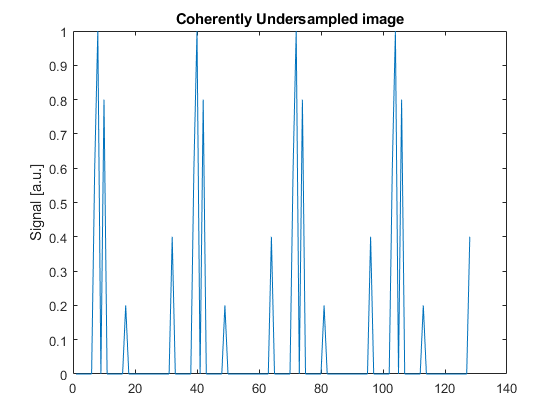

figure; plot(abs(xu)); title('Coherently Undersampled image'); ylabel('Signal [a.u.]');

This is an image of replicas of the sparse non-zero terms in the original image. The replicas are a result of the undersampling in k-space. We cannot reconstruct this signal into the original image because we cannot decipher between replicas and the actual signal. In other words, it is an ill-posed problem with too many solutions.

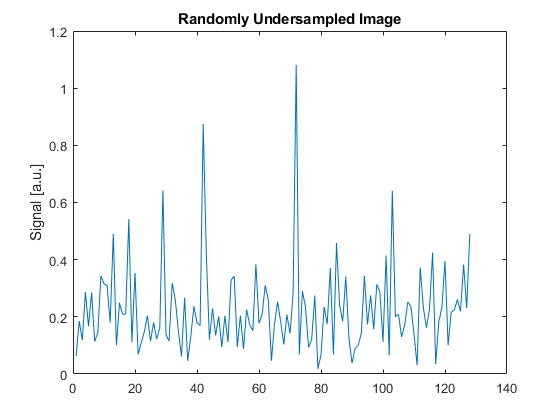

Xr = zeros(1,128);
prm = randperm(128);
Xr(prm(1:32)) = X(prm(1:32));
xr = ifftc(Xr,2)*4;
figure; plot(abs(xr)); title('Randomly Undersampled Image'); ylabel('Signal [a.u.]');

This signal can be reconstructed from the result by applying a denoising algorithm because the incoherent undersampling artifacts resemble noise.

**d) Reconstruction from Randomly Sampled Frequency Domain Data**

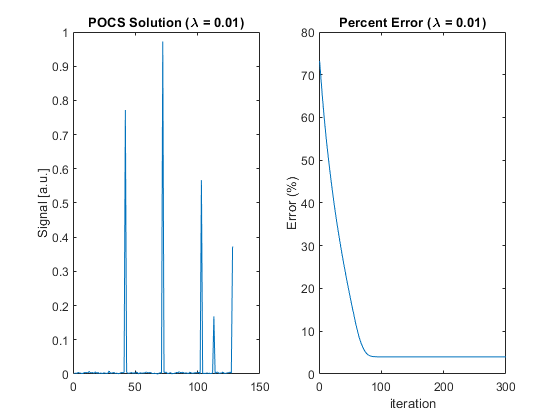

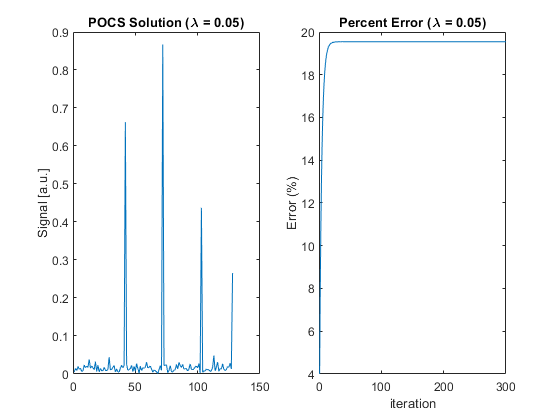

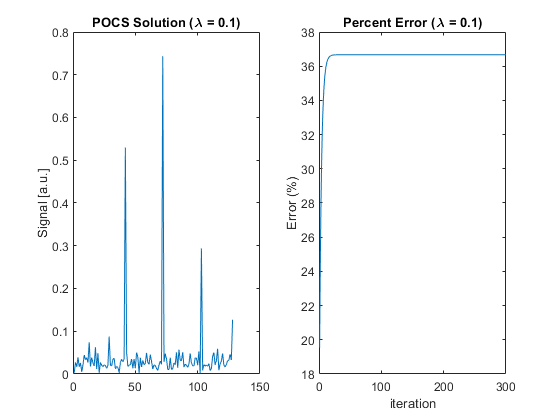

% POCS algorithm
x_true = x;
X = Xr; Y = Xr;
lambda = [0.01 0.05 0.10];
error = zeros(1,300);
for L=1:3
    for ii=1:300
        x2 = ifftc(X,2);
        xst = SoftThresh(x2,lambda(L));
        X = fftc(xst,2);
        for j=1:128
            if  Y(j)~=0
                X(j) = Y(j);
            end 
        end
        error(ii) = sum(abs((x2-x_true)*100/x_true));  
    end
x2 = ifftc(X,2);
Title = ['POCS Solution (\lambda = ' num2str(lambda(L)) ')'];
Title2 = ['Percent Error (\lambda = ' num2str(lambda(L)) ')'];
figure; subplot(1,2,1); plot(abs(x2)); title(Title); ylabel('Signal [a.u.]');
subplot(1,2,2); plot(error); title(Title2); xlabel('iteration'); ylabel('Error (%)');
end

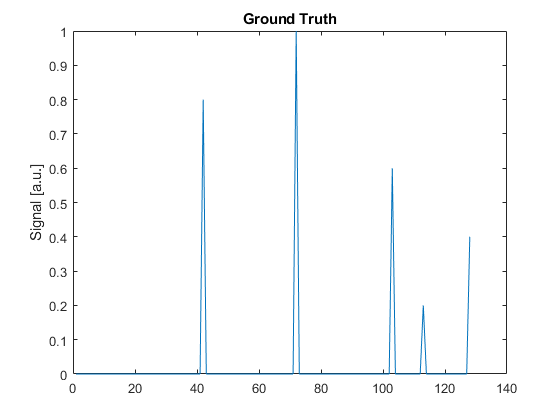

figure; plot(x); title('Ground Truth'); ylabel('Signal [a.u.]');

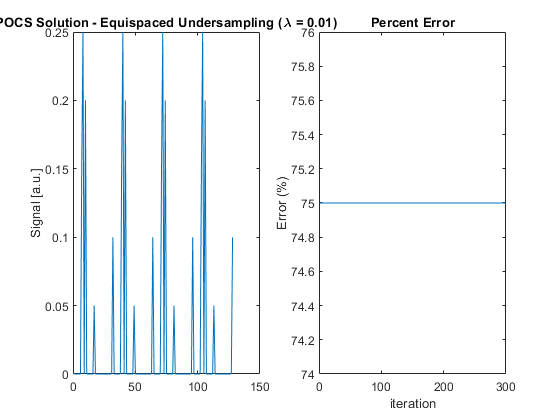


% Repeating with coherently undersampled image
X = Xu; Y = Xu;
for ii=1:300
    x3 = ifftc(X,2);
    xst = SoftThresh(x3,lambda(1));
    X = fftc(xst,2);
    for j=1:128
        if  Y(j)~=0
            X(j) = Y(j);
        end 
    end
    error(ii) = sum(abs((x3-x_true)*100/x_true));  
end
x3 = ifftc(X,2);
figure; subplot(1,2,1); plot(abs(x3)); title('POCS Solution - Equispaced Undersampling (\lambda = 0.01)'); ylabel('Signal [a.u.]');
subplot(1,2,2); plot(error); title('Percent Error'); xlabel('iteration'); ylabel('Error (%)');

In the case where the POCS algorithm is applied to the coherently undersampled data, the error stays the same (at 75% since there are 4 replicas) and the reconstructed image is identical to the aliased image.

## 2) Sparsity of Medical Images

W = Wavelet; %defines a wavelet operator

filterType = 'Daubechies'

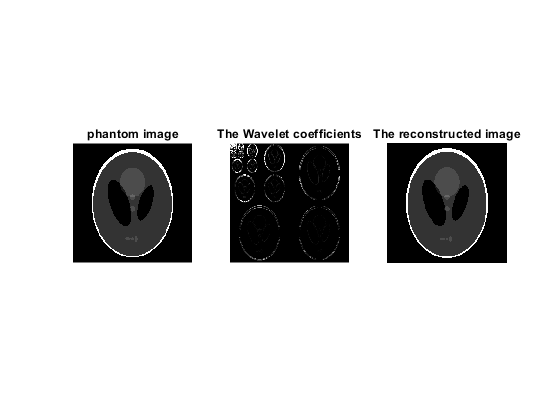

im = phantom(256); % Shep-Logan CT Phantom
im_W = W*im; % computes the wavelet transform
im_rec = W'*im_W; % computes the inverse wavelet transform
figure, subplot(1,3,1), imshow(im,[]), title('phantom image');
subplot(1,3,2), imshow(abs(im_W),[0,1]), title('The Wavelet coefficients');
subplot(1,3,3), imshow(abs(im_rec),[]), title('The reconstructed image');

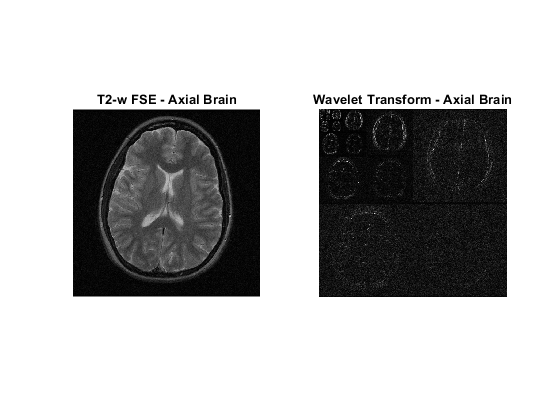


% Load brain and perform wavelet transform
load('brain.mat');
figure, subplot(1,2,1), imshow(abs(im),[]), title('T2-w FSE - Axial Brain');
im_W = W*im;
subplot(1,2,2), imshowWAV(im_W), title('Wavelet Transform - Axial Brain');

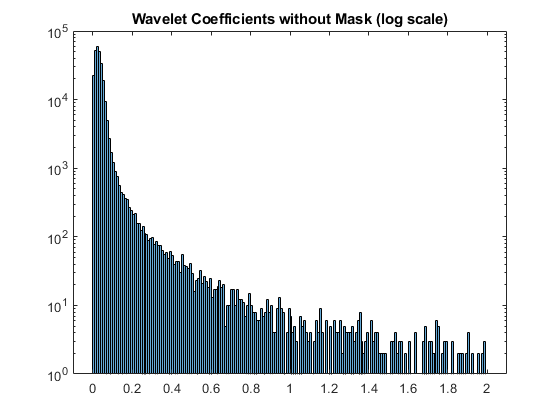


% Threshold at 0.2
f = 0.2;
m = sort(abs(im_W(:)),'descend');
ndx = floor(length(m)*f);
thresh = m(ndx);
im_W_th = im_W.*(abs(im_W)>thresh);  %GOOD TRICK TO THRESHOLD
edges = [0:0.01:2];
figure; histogram(abs(im_W),edges); set(gca,'YScale','log'); title('Wavelet Coefficients without Mask (log scale)'); 

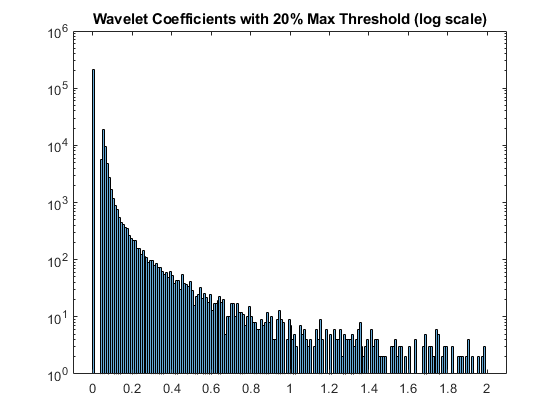

figure; histogram(abs(im_W_th),edges); set(gca,'YScale','log'); title('Wavelet Coefficients with 20% Max Threshold (log scale)');

The small coefficients have been thresholded out. This can be seen in the histogram of the thresholded image, where a portion of the small coefficients are moved to the 0 bin.

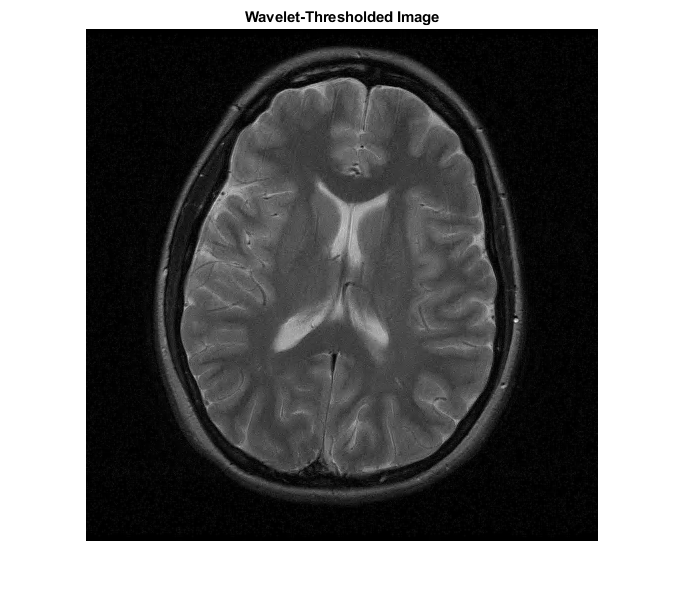

im_rec = W'*im_W_th;
figure, imshow(abs(im_rec),[]), title('Wavelet-Thresholded Image');

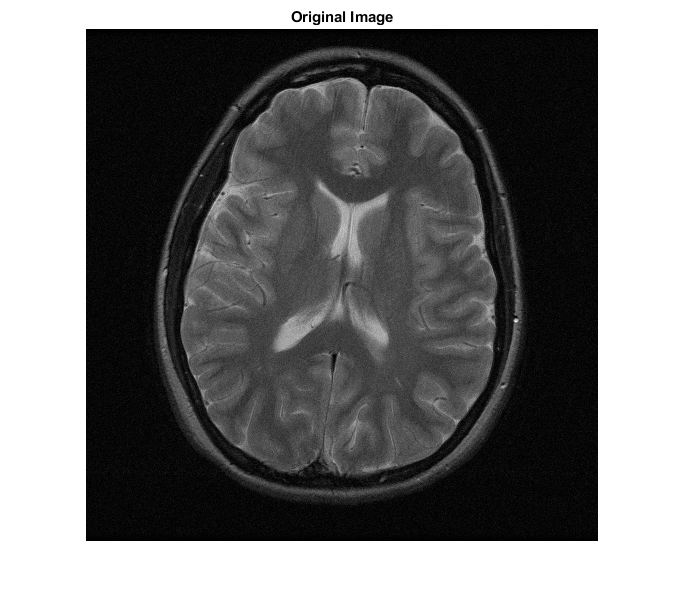

figure, imshow(abs(im),[]), title('Original Image');

The images are very similar in appearance, however the differences are more apparent when we show the pixel-by-pixel difference between the two images. If we look closely at certain structures, it appears that there is more smoothness in the thresholded image. Even more so, some of the noise is removed upon magnification.

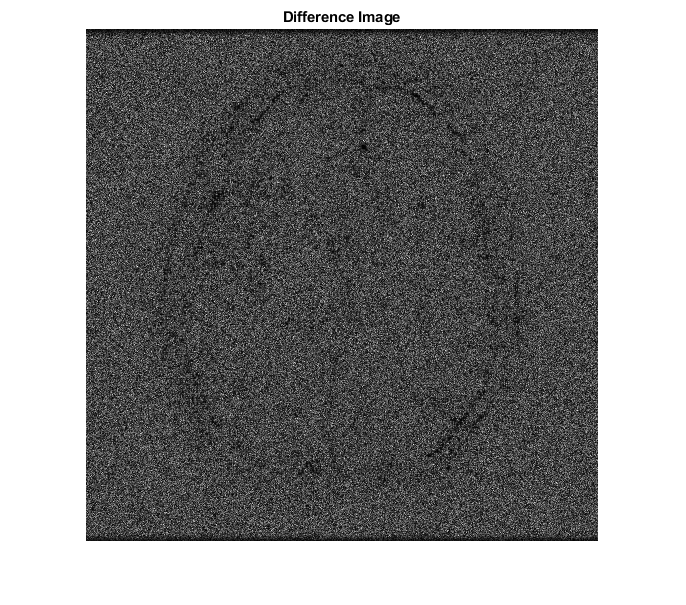

figure, imshow(abs(im-im_rec),[]), title('Difference Image');

The difference image shows many differences spread throughout, with high frequency structures showing little difference. This intuitively makes sense with our previous observation (that noise is reduced), because noise should be spreadout out homogenously over the image. This is why the difference image looks like noise. The fact that sharp, high frequency structures (fat around the skull) are not different between images implies that the wavelet thresholding removed some of the high frequency components. 

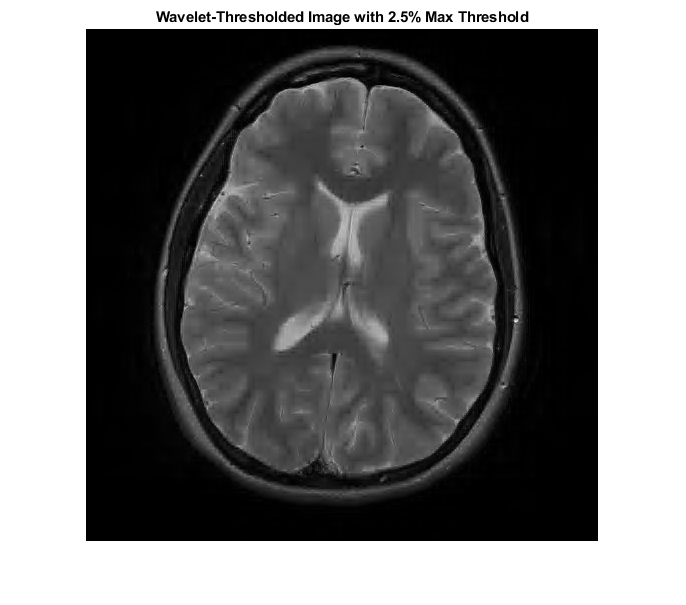

f = [0.2, 0.125, 0.10, 0.05, 0.025];
ndx = floor(length(m)*f);
thresh = m(ndx);
im_W_th = zeros(512,512,5);
im_rec = zeros(512,512,5);
for i=1:5
    im_W_th(:,:,i) = im_W.*(abs(im_W)>thresh(i));
    im_rec(:,:,i) = W'*im_W_th(:,:,i);
end 
figure, imshow(abs(im_rec(:,:,5)),[]), title('Wavelet-Thresholded Image with 2.5% Max Threshold');

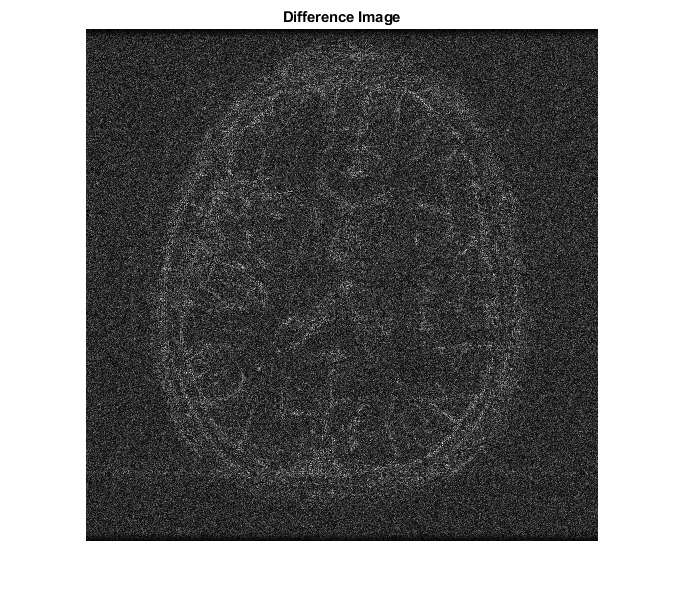

figure, imshow(abs(im-im_rec(:,:,5)),[]), title('Difference Image');

From this, it is easy to see that the sparsity of the masked image is in the low frequeny aspects of the image (once the high frequency has been removed). This can be readily seen in the difference images.

## 3) Compressed Sensing Reconstruction

### a) Non-Uniform Random Sampling

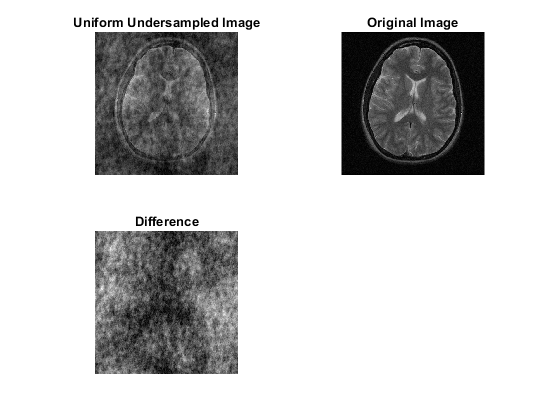

M = fft2c(im);
Mu = (M.*mask_unif)./pdf_unif;
imu = ifft2c(Mu);
figure, subplot(2,2,1), imshow(abs(imu),[]); title('Uniform Undersampled Image');
subplot(2,2,2), imshow(abs(im),[]); title('Original Image');
subplot(2,2,3), imshow(abs(im-imu),[]); title('Difference');

Although the aliasing appears as noise, it is not white noise. Instead, it is incoherent artifacts. 

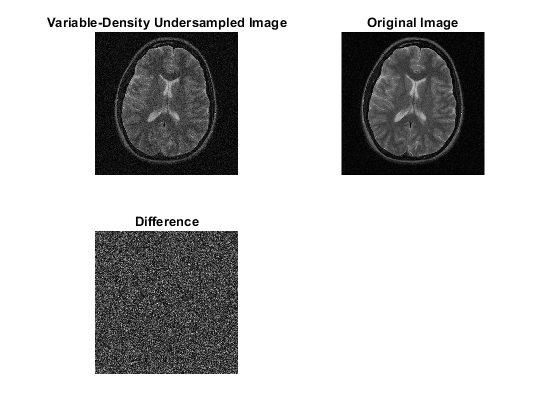

Mu2 = (M.*mask_vardens)./pdf_vardens;
imu2 = ifft2c(Mu2);
figure, subplot(2,2,1), imshow(abs(imu2),[]); title('Variable-Density Undersampled Image');
subplot(2,2,2), imshow(abs(im),[]); title('Original Image');
subplot(2,2,3), imshow(abs(im-imu2),[]); title('Difference');

figure;

The variable density type mask has a much better "noise" appearance compared to the uniform undersampling. 

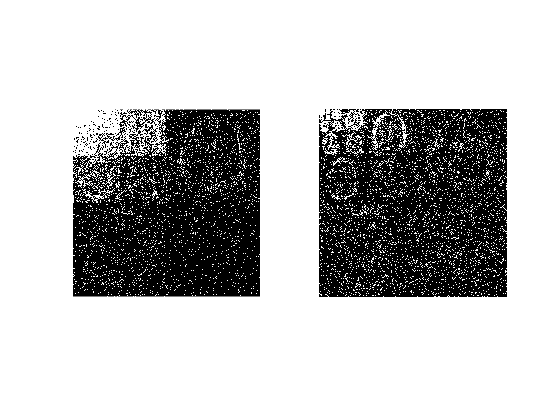

lambda = 0.1; % CHANGE THIS
imuW = W*imu; imuW2 = W*imu2;
figure; subplot(1,2,1); imshow(abs(imuW)>lambda,[]); 
subplot(1,2,2); imshow(abs(imuW2)>lambda,[]); 

### b) Reconstruction from Random Sampled k-Space Data

### Functions

function [xhat] = SoftThresh(y,lambda)

xhat = zeros(1,length(y));
for i=1:length(y)
    if abs(y(i)) > lambda
        xhat(i) = (abs(y(i)) - lambda)*(y(i)/abs(y(i)));
    else
        xhat(i) = 0;
    end
end 

end